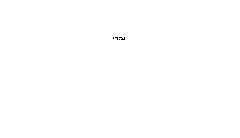

braille = imread('test3.png');
imshow test3.png


brailleBW = rgb2gray(braille); % to only have 1 dimension
brailleBW(brailleBW==0) = 1; % changes 0 to 1
brailleBW(brailleBW==255) = 0; % changes 255 to 0

[rows, columns] = size(brailleBW); 


%divide matrix into rows of 5 and columns of 3 

c = columns / 2; %finds amount of columns
r = rows / 3; % finds amount of rows

ro = size(brailleBW, 1) / r * ones(1, r); % creats a vector that is the same length as r and adds to rows
co = size(brailleBW, 2) / c * ones(1, c); % creats a vector that is the same length as c and adds to columns

Letter = mat2cell(brailleBW, ro, co) % splits image into smaller matrices of each letter

Letter = 1×6 cell array
    {3×2 uint8}    {3×2 uint8}    {3×2 uint8}    {3×2 uint8}    {3×2 uint8}    {3×2 uint8}


used the alphabet from this [https://www.pharmabraille.com/pharmaceutical-braille/the-braille-alphabet/](https://www.pharmabraille.com/pharmaceutical-braille/the-braille-alphabet/) website for the following code.

% make a list of each character in matrix form
A = [1 0; 0 0; 0 0];
B = [1 0; 1 0; 0 0];
C = [1 1; 0 0; 0 0];
D = [1 1; 0 1; 0 0];
E = [1 0; 0 1; 0 0];
F = [1 1; 1 0; 0 0];
G = [1 1; 1 1; 0 0];
H = [1 0; 1 1; 0 0];
I = [0 1; 1 0; 0 0];
J = [0 1; 1 1; 0 0];
K = [1 0; 0 0; 1 0];
L = [1 0; 1 0; 1 0];
M = [1 1; 0 0; 1 0];
N = [1 1; 0 1; 1 0];
O = [1 0; 0 1; 1 0];
P = [1 1; 1 0; 1 0];
Q = [1 1; 1 1; 1 0];
R = [1 0; 1 1; 1 0];
S = [0 1; 1 0; 1 0];
T = [0 1; 1 1; 1 0];
U = [1 0; 0 0; 1 1];
V = [1 0; 1 0; 1 1];
W = [0 1; 1 1; 0 1];
X = [1 1; 0 0; 1 1];
Y = [1 1; 0 1; 1 1];
Z = [1 0; 0 1; 1 1];

% %compare it to the split cells. 
% for j = 1:co %for all the columns of letter cell array
%     for i = 1:ro %for all the rows of letter cell array
%            if cell(i,j) == A %basically compare each cell to each character array, once it has determined a cell is a specific character it will set it equal to that character.
%                cell(i,j) = letterA
%            elseif 
%                %continue the if statement to inclue each character
%            end
%     end
% end

% a voice read them off